% code for plot results of Widefield imaging, which contain functions listed
% below
% Align neural activity of different trails by behavior events
% plot aligned neural activity of each trial (line + heatmap)
% plot activity correlation of each brain region
% plot neural activity sequence averaged by specific timebin
% plot neural activity averaged by specific behavior

% cut and align the neural activity based on task event written by NY

clear all;
close all;
clc;

Animal = 'tph189';
Date = '20230418';
totalTrial = 150;
Key = 'uniform';
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022/';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation'  filesep Date '_' Animal '_' Key]; % Linux
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% behavior_data = behavior_neural_time_convolved_zscored;
output_dir = '/home/naohiro/Desktop/Doya_rotation/analysis/output/';

% neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
% neural_activity_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces.csv'],'NumHeaderLines',0);
neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);

sum(strcmp(table2array(neural_property_table(:,'Status')),'accepted'))

ans = 191

strcmp(neural_property_table(:,'Status'),'accepted')

ans = logical
   0


acc_neural_activity_data

acc_neural_activity_data =     5.9168   20.2242   31.3767    0.9025   -0.9259   10.1516    9.5282    1.9840   18.5185   -1.5787    0.8142   23.1989   -0.2973    3.8236   44.8459    7.4560    7.2730   -2.5544   11.9062    3.3925    3.8500   13.8883   13.9680   11.1083   -2.5511   17.9295    3.0862    0.3762    6.7682   31.9482   10.8249   -8.5090    1.4636    0.3969   13.1603    5.9127   18.7914   13.5945    6.7703   14.0904    7.6183   20.0182    6.1259    6.2503    4.8550    4.1216    1.1430    7.0391   -0.2430   12.6287
    6.0606   22.3476   33.2336    2.3410   -2.0958    7.4441    9.6469    2.6039   18.3217   -2.1294    1.8055   24.4363   -1.0482    3.9889   45.2023    6.5107    7.5614   -3.5851   11.0937    4.0323    3.4598   10.8773   12.7359   13.2328   -2.0763   15.1794    2.0097    2.4040    7.9122   31.7793    8.7858   -6.9195    2.5876    0.3800   14.0709    3.6880   18.4466   12.4099    6.2106   16.9585    8.0498   17.0875    6.0070    7.4223    2.5130    4.1384    1.3308  

acc_neural_property_data

acc_neural_property_data =   255.0000  255.0000  255.0000   69.0000   17.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000   37.0000   48.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000   24.0000   10.0000    1.0000    9.8489    1.0000
  255.0000  255.0000  255.0000   89.0000   11.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000   87.0000   20.0000    1.0000    8.0623    1.0000
  255.0000  255.0000  255.0000  146.0000   37.0000    1.0000    8.9443    1.0000
  255.0000  255.0000  255.0000  146.0000   66.0000    1.0000    8.5440    1.0000
  255.0000  255.0000  255.0000  162.0000   32.0000    1.0000    8.0623    1.0000
  255.0000  255.0000  255.0000  140.0000   68.0000    1.0000    8.5440    1.0000
  255.0000  255.0000  255.0000  141.0000   48.0000    1.0000    9.4868    1.0000



% clear all;
% close all;
% clc;
% 
% CompNum = 40;
% 
% Initial = 'NY';
% Animal = 'tlx56';
% Date = '221219';
% totalBlock = 10;
% Key = 'min';
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\';

fps = 20;
% make sure the order of the rows in the table should line up with the order of the names in the imaging file
timepoints_table = readtable([working_directory Date filesep Initial '_' Animal filesep 'BehaviorRecord.csv'],'NumHeaderLines',1);

Unrecognized function or variable 'Initial'.

before = 1000;
after = 4000;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% load neural activity data
cd([working_directory Date filesep Initial '_' Animal filesep 'ICA\ICA_40']);
load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],'RecICA_Temp','-mat');

% cut and align each data
% how to deal with data which do not contain enough before or after
% timepoints
% colum 23: lift-1sec (ms)
timepoints = [table2array(timepoints_table(1:totalBlock,23))*fps/1000 table2array(timepoints_table(1:totalBlock,23))*fps/1000+(before+after)*fps/1000];
% in case there are float (not occured usually)
timepoints = round(timepoints);

% save aligned data 
% set Events to fit the style of CR_Reconstruction.mlx

RecICA_lift{totalBlock} = [];
for block = 1:totalBlock
    disp(['Calculating imaging block ' num2str(block)]);
    RecICA_lift{block} = RecICA_Temp{block}(:,timepoints(block,1):timepoints(block,2));
end

save([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],'RecICA_lift','-append');

% plot neural activity
% addpath([working_directory 'PCA_and_ICA\Subaxis']);
ylimit=[0 50];
mean_acc_neural_activity = mean(acc_neural_activity_data,2);
figure
% for i = 1:size(acc_neural_activity_data,2)
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    for j = 1:size(acc_neural_activity_data,2)
        hold on 
        r = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,j));
        hold off
    end
    alpha(r,0.1);

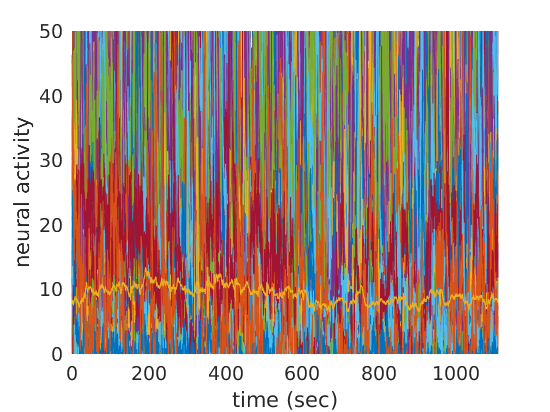

    hold on
    b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,mean_acc_neural_activity);
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 
    ylabel('neural activity');
    xlabel('time (sec)')


% end
% saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_all_activity.png']);

% plot neural activity heatmap
climit = [0 50]

climit =      0    50


figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = transpose(acc_neural_activity_data)
%     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     5.9168    6.0606    5.4073    5.3635    6.0052    6.6081    7.5074    7.5049    7.7470    6.0865    6.7907    7.8541    8.2476    8.5221    9.1043    9.8447    8.0681    8.4683   10.3210    7.8551    9.9948    8.5776    9.9267    8.5740    7.2622    9.1916    7.7315    8.3588    8.6245   10.1688   10.6351   10.7501    9.3659   10.2979    8.3088   10.1923    8.4285    8.3673    6.0878    8.3804    5.5488    7.5377    7.1669    8.3749    8.9075    7.5200    6.3222    9.8452    8.2560    9.1669
   20.2242   22.3476   25.6047   25.0432   25.4423   29.8142   31.1866   31.1710   34.7834   34.6079   36.1677   39.7276   41.5919   40.3872   42.5532   43.0781   42.8763   45.2799   43.9024   44.7659   44.8881   45.3858   46.3050   44.9260   44.7752   46.1913   43.3529   40.0067   42.1152   41.8325   42.0161   43.1156   41.0672   37.8375   36.3285   33.9099   34.1466   33.9021   32.6354   32.5453   32.1912   32.7103   32.6388   34.7740   34.5076   35.0292   35.3819   33.9333   32.1304 

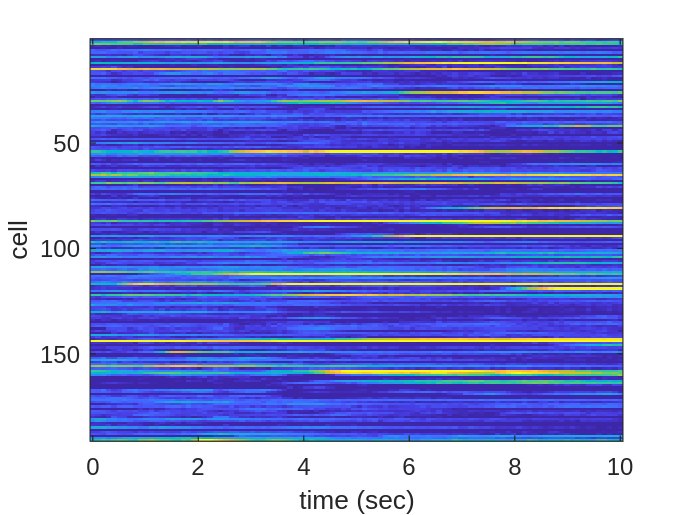

    imagesc(0:0.1:(size(acc_neural_activity_data,1)-1)/10,1:size(acc_neural_activity_data,2),image,clims);
%     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
    ylabel('cell');
    xlabel('time (sec)')

% end

filename = [output_dir Date '_' Animal, '_all_activity_heatmap.png'];

Unrecognized function or variable 'output_dir'.

saveas(gcf,filename);
% close all;

addpath([working_directory 'Utility' filesep 'Subaxis']);
example_num = 5;
display_start = 113;
ylimit=[0 150];
figure
for i = 1:example_num
    subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
    b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,display_start+i));
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 
    xlim([0 (size(acc_neural_activity_data,1)-1)/10])
%     ylabel('neural activity');
%     xlabel('time (sec)')
end
filename = [output_dir Date '_'  Animal, '_exmple_activity_traces.png'];
saveas(gcf,filename);

0:0.1:(size(acc_neural_activity_data,2)-1)/10

% plot event triggered neural activity
force_thr = 50;
fps = 10;
before_event = 1;
after_event  = 2;
norm = 2; %0:no normalization or 1:normalization or 2:z scored

load([data_folder filesep Animal '_behavior_' Date '_' Key '.mat']);

% 'behavior_neural_time'
trial_start = behavior_neural_time(:,3);
trial_end   = behavior_neural_time(:,4);
force       = behavior_neural_time(:,7)

force =    -2.5121
   -2.8159
   -3.3222
   -2.5121
   -2.9918
   -2.6080
   -2.7040
   -1.7615
   -1.9760
   -1.9365


reward      = behavior_neural_time(:,8);
% find index of each event
trial_start_idx = find(trial_start == 1);
trial_end_idx   = find(trial_end == 1);
force_idx       = find(force > force_thr);
reward_idx      = find(reward == 1); % TODO: change to get only first reward idx among 3
% idxs = [trial_start_idx, trial_end, force_idx, reward_idx];
% event_acts = []; % trial_start_act, trial_end_act, force_act, reward_act
trial_start_act = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
trial_end_act   = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
force_act       = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
reward_act      = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);

% only count first idx in 1 second
temp_force_idx = force_idx(1);
for i = 2:length(force_idx)
    if force_idx(i) - temp_force_idx(end) >= fps
        temp_force_idx(end+1) = force_idx(i);
    end
end
force_idx = temp_force_idx;

temp_reward_idx = reward_idx(1);
for i = 2:length(reward_idx)
    if reward_idx(i) - temp_reward_idx(end) >= fps
        temp_reward_idx(end+1) = reward_idx(i);
    end
end
reward_idx = temp_reward_idx;

% for i = 1:size(idxs,2)
%     temp_event_acts = zeros(size(acc_neural_activity_data,1),fps*(before_event+after_event));
exception_count = 0;
for j = 1:length(trial_start_idx)
    if trial_start_idx(j)-fps*before_event<=0 | trial_start_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        trial_start_act = trial_start_act+transpose(acc_neural_activity_data(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:)); 
    end
end
trial_start_act = trial_start_act/(length(trial_start_idx)-exception_count);
if norm == 1
    trial_start_act = normalize_rows(trial_start_act);
elseif norm ==2
       trial_start_act = zscore_rows(trial_start_act); 
end
[M,I] = max(trial_start_act,[],2);
trial_start_act = cat(2,I,trial_start_act);
trial_start_act = sortrows(trial_start_act);
trial_start_act(:,1) = [];

exception_count = 0;
for j = 1:length(trial_end_idx)
    if trial_end_idx(j)-fps*before_event<=0 | trial_end_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        trial_end_act = trial_end_act+transpose(acc_neural_activity_data(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:)); 
    end
end
trial_end_act = trial_end_act/(length(trial_end_idx)-exception_count);
if norm == 1
    trial_end_act = normalize_rows(trial_end_act);
elseif norm ==2
   trial_end_act = zscore_rows(trial_end_act); 
end
[M,I] = max(trial_end_act,[],2);
trial_end_act = cat(2,I,trial_end_act);
trial_end_act = sortrows(trial_end_act);
trial_end_act(:,1) = [];

exception_count = 0;
for j = 1:length(force_idx)
    if force_idx(j)-fps*before_event<=0 | force_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        force_act = force_act+transpose(acc_neural_activity_data(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:)); 
    end
end
force_act = force_act/(length(force_idx)-exception_count);
if norm == 1
    force_act = normalize_rows(force_act);
elseif norm ==2
       force_act = zscore_rows(force_act); 
end
[M,I] = max(force_act,[],2);
force_act = cat(2,I,force_act);
force_act = sortrows(force_act);
force_act(:,1) = [];

exception_count = 0;
for j = 1:length(reward_idx)
    if reward_idx(j)-fps*before_event<=0 | reward_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        reward_act = reward_act+transpose(acc_neural_activity_data(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:)); 
    end
end
reward_act = reward_act/(length(reward_idx)-exception_count);
if norm == 1
    reward_act = normalize_rows(reward_act);
elseif norm ==2
   reward_act = zscore_rows(reward_act); 
end
[M,I] = max(reward_act,[],2);
reward_act = cat(2,I,reward_act);
reward_act = sortrows(reward_act);
reward_act(:,1) = [];
% end

% plot neural activity heatmap
if norm == 1
    climit = [0 1];
elseif norm == 2
    climit = [-2 2];
else
    climit = [0 50];
end
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_start_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.2917    1.1854    1.1840    1.0345    1.1021    1.0742    0.9577    0.8140    0.8900    1.0740    1.1266    0.7504    0.8469    0.5804    0.4421    0.0877   -0.1915   -0.4929   -0.6989   -0.7268   -0.7405   -0.9387   -0.9615   -1.2328   -1.1702   -1.2142   -1.0437   -1.1330   -1.1856   -1.3186   -1.3926
    1.3860    0.7160    1.1336    0.9369    0.7800    0.9774    0.8748    0.1604    0.2277    0.1696    0.8573    1.2432    1.3616    0.9650    0.5327    0.6801    0.2809    0.3299   -0.2096   -0.1471   -0.8254   -0.8924   -1.1820   -0.8615   -1.5411   -1.7003   -1.2359   -1.4927   -1.2339   -1.3866   -0.9048
    1.4026    1.2543    1.3238    1.3157    1.3833    1.3388    1.1648    1.1886    1.1219    0.8981    0.7529    0.6093    0.3228    0.0683   -0.0993   -0.5497   -0.7583   -0.8921   -1.0330   -1.0685   -1.1635   -1.1470   -1.1840   -1.1748   -1.0935   -0.9840   -0.5892   -0.7871   -0.6996   -0.4679   -0.4540
    1.4069    1.3841    1.3981    1.3076    1.2901    1.259

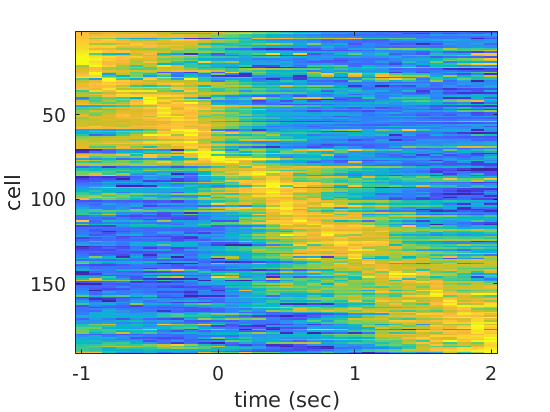

    imagesc(-before_event:0.1:after_event,1:size(acc_neural_activity_data,2),image,clims);
    ylabel('cell');
    xlabel('time (sec)')

% end

% filename = [output_dir Date '_' Animal, '_trial_start_eta_activity_heatmap.png'];
% saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_end_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.1191    1.0453    1.1012    1.0056    1.0839    0.9883    0.8981    0.8693    0.9753    0.9836    0.9906    0.8888    0.9231    0.6720    0.4904    0.1719   -0.0815   -0.3722   -0.3728   -0.5291   -0.6289   -0.8604   -0.8557   -1.1139   -1.1578   -1.1620   -1.2537   -1.3154   -1.3737   -1.5204   -1.6091
    1.3743    0.9144    0.5611    0.8595    0.5696    1.2594    0.8110    0.8435    0.1786   -0.2520    1.1253    1.1962    0.9490    0.0302   -0.9186   -0.1375   -0.1835   -1.0485    0.1827    0.3313    0.6299    0.0203    0.1809    0.7873   -0.5895   -1.5815   -1.6867   -1.3579   -1.6074   -1.8113   -1.6302
    1.3754    1.1503    1.0293    0.8263    0.9354    1.0911    0.7983    0.6290    0.4886    0.4189   -0.1199   -0.2628   -0.9977   -1.0694   -1.6161   -1.7202   -1.7598   -1.6620   -1.3604   -1.2201   -0.8227   -0.4700   -0.1092   -0.1125    0.3714    0.1284    0.5417    0.6962    0.8512    0.8978    1.0735
    1.4327    1.3369    1.4172    1.3415    1.3201    1.371

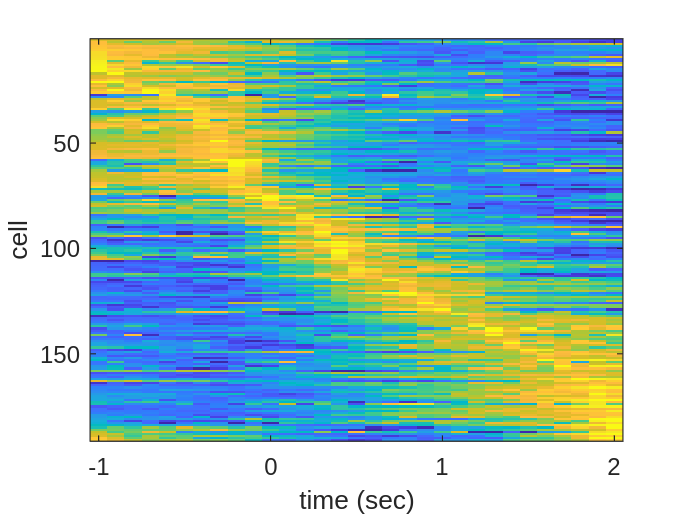

    imagesc(-before_event:0.1:after_event,1:size(acc_neural_activity_data,2),image,clims);
    ylabel('cell');
    xlabel('time (sec)')

% end

% filename = [output_dir Date '_' Animal, '_trial_end_eta_activity_heatmap.png'];
% saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = force_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.3910    0.5425    0.8853    0.4242   -0.0861   -0.8381   -1.3432   -1.7774   -1.4216   -1.6928   -1.6888   -1.6077   -1.7173   -0.4486    0.1628    0.3603    0.9536   -0.2788    0.8917    0.2810    0.8702    0.5938    0.9048    1.1838    1.1173    0.3903    0.2731    0.5747    0.5938    0.3685    0.1376
    1.4911    1.3284    1.3001    1.2128    1.1980    1.4008    1.2806    1.2985    1.2000    1.0938    0.6968    0.3054   -0.2502   -0.5513   -0.8253   -1.1100   -1.2561   -1.3187   -1.2437   -1.0739   -1.1744   -0.9864   -0.9163   -0.6174   -0.6459   -0.4585   -0.4202   -0.2550   -0.2705   -0.1581   -0.2746
    1.5607    1.1634    0.8949    1.3068    0.7526    0.8454    1.3330    1.4262    1.4028    0.7624    0.9756    0.5686    0.3040    0.2644   -0.5145   -0.9430   -1.3357   -1.2480   -1.4113   -1.0492   -1.4326   -1.0127   -1.2195   -0.9779   -0.2988   -0.4603   -0.9314   -0.4020   -0.2406   -0.2898    0.2065
    1.6046    1.5575    1.5864    1.5184    1.5473    1.382

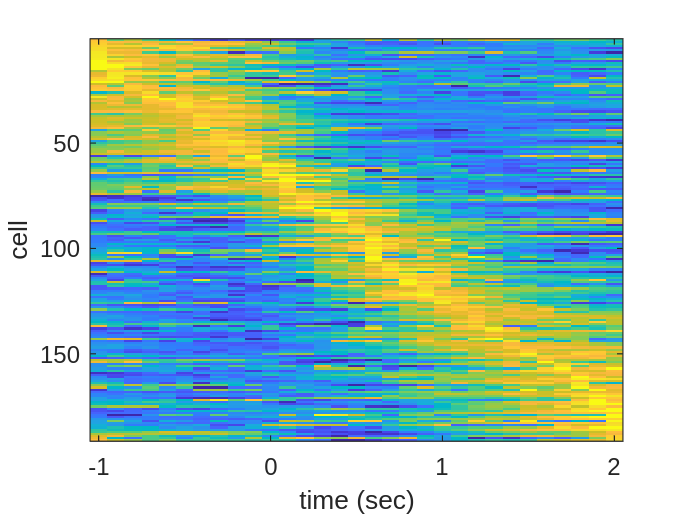

    imagesc(-before_event:0.1:after_event,1:size(acc_neural_activity_data,2),image,clims);
    ylabel('cell');
    xlabel('time (sec)')

% end

% filename = [output_dir Date '_' Animal, '_force_eta_activity_heatmap.png'];
% saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = reward_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.1066    1.0918    0.9715    0.4821    1.0405    1.0115    0.7940    0.8987   -0.0167   -0.1640   -0.7368   -0.7373   -1.2304   -1.9198   -2.0888   -1.8414   -1.4956   -1.1086   -0.8667   -0.3852   -0.4173   -0.2481    0.5172    0.7242    0.6758    0.3575    0.9167    0.8329    0.8632    0.6690    0.3035
    1.2206    0.9787    0.8569    0.8295    0.8428    0.8331    0.9021    0.8752    0.6179    0.6098    0.5660    0.6619    1.1369    0.7216    0.8674    0.6262    0.4433    0.1476    0.0511   -0.1858   -0.4904   -0.7088   -1.0083   -1.1716   -1.1453   -1.1311   -1.6687   -1.4990   -1.5415   -1.7740   -1.4639
    1.2880    1.2736    1.1718    1.1772    1.1564    1.1129    1.2464    1.2657    1.2164    1.1133    0.9687    0.7116    0.5282    0.1808   -0.0321   -0.2225   -0.5631   -0.7812   -0.9191   -0.8628   -1.0222   -1.1460   -1.1636   -1.1333   -0.9953   -0.9832   -0.9022   -1.0158   -0.9152   -0.9528   -0.8007
    1.5418    1.3879    1.4811    1.3831    1.3295    1.291

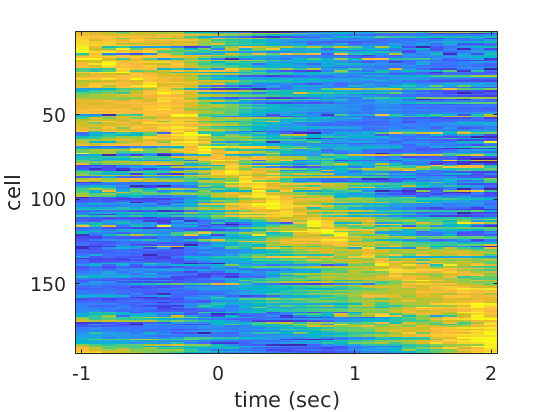

    imagesc(-before_event:0.1:after_event,1:size(acc_neural_activity_data,2),image,clims);
    ylabel('cell');
    xlabel('time (sec)')

% end

% filename = [output_dir Date '_' Animal, '_reward_eta_activity_heatmap.png'];
% saveas(gcf,filename);
% close all;

% Plot neural activity of each trial and make activity correlation matrix from RecICA_lift written by NY

CompNum = 40;
Animal = 'tlx56';
Date = '221219';
Events = {'lift'}; % 'lift' or 'Temp'
Initial = 'NY'; 
Key = 'min';
Block = 10;
totalBlock = 10;
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\';

close all
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% load neural activity data
cd([working_directory Date filesep Initial '_' Animal ])
addpath([working_directory Date filesep Initial '_' Animal filesep 'ICA\ICA_40']);
load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],'RecICA_Temp','RecICA_lift','-mat');
samp_img = reshape(RecICA_lift{Block},[128 128 size(RecICA_lift{Block}, 2)]);
mkdir([working_directory Date filesep Initial '_' Animal filesep 'neural_act_outputs'])
output_dir = [working_directory Date filesep Initial '_' Animal filesep 'neural_act_outputs' filesep];
imwrite(samp_img(:,:,1),[output_dir sprintf('RecICA_lift_%d.png', Block)]);

% set ROI to compare neural activity
brain_roi_name = ['A' 'B' 'C' 'D' 'E' 'F']
brain_roi = [[63, 11]; [73, 12]; [30, 59];  [107, 66]; [45, 93]; [89, 94]];
y_reverse = 1; % 1 if brain_roi is specified by ImageJ
% set how many pixels expand
pix_exp = 2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
brain_roi_temp = brain_roi;
if y_reverse == 1
    for i = 1:length(brain_roi)
        brain_roi(i,1) = brain_roi_temp(i,2);
        brain_roi(i,2) = brain_roi_temp(i,1);
    end
end

% calculate neural activity of each roi
roi_activities = zeros(length(brain_roi), totalBlock, size(RecICA_lift{Block}, 2));

for j = 1:totalBlock
    RecICA_lift_reshape = reshape(RecICA_lift{j},[128 128 size(RecICA_lift{j}, 2)]);
%     roi_activities = zeros(length(brain_roi),size(RecICA_Temp{j}, 2));
    % expand roi
    for i = 1:length(brain_roi)    
        roi_RecICA_lift = RecICA_lift_reshape(brain_roi(i,1)-pix_exp:brain_roi(i,1)+pix_exp, brain_roi(i,2)-pix_exp:brain_roi(i,2)+pix_exp, :); 
        % take mean of neural activity
        mean_roi_activity = reshape(mean(mean(roi_RecICA_lift)),[1 size(RecICA_lift{j}, 2)]);
        roi_activities(i,j,:) = mean_roi_activity;
    end
end

% calculate Block mean of neural activity of each roi
block_mean_roi_activities = reshape(mean(roi_activities,2),[size(roi_activities, 1) size(roi_activities, 3)]);

% calculate correlation of neural activity
mean_RecICA_lift = zeros(size(RecICA_lift{1}));
for j = 1:totalBlock
    mean_RecICA_lift = mean_RecICA_lift + RecICA_lift{j};
end
mean_RecICA_lift = mean_RecICA_lift/totalBlock;
R_roi_act = zeros(length(brain_roi), 128*128);
for i = 1:length(brain_roi)
    for k = 1:128*128
        temp_coeff = corrcoef(transpose(block_mean_roi_activities(i,:)), transpose(mean_RecICA_lift(k,:)));
        R_roi_act(i,k) = temp_coeff(2,1);
    end
end

% plot neural activity of specific brain region
ylimit = [-0.1 0.2];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
addpath([working_directory 'PCA_and_ICA\Subaxis']);
figure
for i = 1:length(brain_roi) 
    subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    for j = 1:totalBlock
        hold on 
        r = plot(-1:0.05:4,squeeze(roi_activities(i,j,:)));
        hold off
    end
    alpha(r,0.1);
    hold on
    b = plot(-1:0.05:4,block_mean_roi_activities(i,:));
    title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 

end
saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_all_activity.png']);

% plot neural activity heatmap of specific brain region
% x:time, y:blocks, color:df/f
climit = [0 0.2];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
set(gcf,'color','w');
for i = 1:length(brain_roi) 
    subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    imagesc(-1:0.05:4,1:10,image,clims);
end

filename = [output_dir Animal, '_' num2str(clims(2)) '_all_activity_heatmap.png'];
saveas(gcf,filename);
close all;

% plot correlation heatmap

figure
set(gcf,'color','w')
for i = 1:length(brain_roi)
    subaxis(1,length(brain_roi),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
    clims = [-1 1]; 
    image = R_roi_act(i,:);
    imagesc(reshape(image,[128 128]),clims)
    axis square
    axis off
    title([Animal ' corr' brain_roi_name(i)], 'FontSize',4);
end
saveas(gcf,[output_dir Animal '_activity_correlation_map.png']);

% Output tiff images from matrix for visualization written by NY
clear all;
close all;
clc;

CompNum = 40;

Initial = 'NY';
Animal = 'tlx56';
Date = '221219';
totalBlock = 10;
Block = 8;
Key = 'min';
Event = 'lift'; % 'Temp'
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% for visualizing images after PCA/ICA
cd([working_directory Date filesep Initial '_' Animal filesep 'ICA\ICA_40']);
event_act = ['RecICA_' Event];
load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],event_act,'-mat');
mkdir(['RecICA_' Event '_out_' Key]);
if strcmp(Event, 'Temp')
    max(max(RecICA_Temp{Block}))
    target_RecICA = Rec_ICA_Temp;
elseif strcmp(Event, 'lift')
    max(max(RecICA_lift{Block}))
    target_RecICA = RecICA_lift;
end

clims = [0 0.3]; % adjust by using max(max(RecICA_Temp{1})) (upper limit)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:size(target_RecICA{Block},2)
% for i = 1:size(RecICA_lift{Block},2)
    figure;
    set(gcf,'color','w');
    image = target_RecICA{Block}(:,i);
%     image = RecICA_lift{Block}(:,i);
    imagesc(reshape(image,[128 128]),clims);
    colormap jet;
    axis square;
    axis off;
    filename = ['RecICA_' Event '_out_' Key filesep 'RecICA_' num2str(Block) '_', num2str(i), '.tif'];
    saveas(gcf,filename);
end
close all

% for visualization of event aligned sequence

fps = 20;
% Specify how many milliseconds before and after the event to plot and how many milliseconds between plots
before = 1000;
after = 4000;
inter = 50;
output_dir = [working_directory Date filesep Initial '_' Animal filesep 'neural_act_outputs' filesep];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% calculate block average RecICA neural activity

mean_RecICA_lift = zeros(size(RecICA_lift{1}));
for j = 1:totalBlock
    mean_RecICA_lift = mean_RecICA_lift + RecICA_lift{j};
end
mean_RecICA_lift = mean_RecICA_lift/totalBlock;
max(max(mean_RecICA_lift))

clims = [0 0.2]; % adjust by upper limit

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% plot averaged neural activity sequences
addpath([working_directory 'PCA_and_ICA\Subaxis']);
figure;
set(gcf,'color','w');
for i = 17:36 %1:(before+after)/inter   
    subaxis(4,5,i-16, 'Spacing', 0.02, 'Padding', 0, 'Margin', 0.015);
    image = mean(mean_RecICA_lift(:,inter*(i-1)*fps/1000+1:inter*i*fps/1000),2);
    imagesc(reshape(image,[128 128]),clims);
    colormap jet;
    axis square;
    axis off;
    title(['RecICA ' num2str(inter*(i-1)-before) ' ms'], 'FontSize',4);
end
saveas(gcf,[output_dir Animal '_' Event '_' Key '_' num2str(clims(2)) '_RecICA_sequence.png']);
close all

% for visualization of reaching event aligned sequence

fps = 20;
events = {'before' 'extend' 'grasp' 'wisdraw' 'after'};
timepoints_table = readtable([working_directory Date filesep Initial '_' Animal filesep 'BehaviorRecord.csv'],'NumHeaderLines',1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% colum 23: lift-1sec (ms)
timepoints = [table2array(timepoints_table(1:totalBlock,23))*fps/1000 table2array(timepoints_table(1:totalBlock,16))*fps/1000 table2array(timepoints_table(1:totalBlock,18))*fps/1000 table2array(timepoints_table(1:totalBlock,21))*fps/1000 table2array(timepoints_table(1:totalBlock,22))*fps/1000 table2array(timepoints_table(1:totalBlock,23))*fps/1000+(before+after)*fps/1000];
% in case there are float (not occured usually)
timepoints = round(timepoints);
% replace 0 to end (ms): table2array(timepoints_table(1:totalBlock,22))*fps/1000 
zero_idx = timepoints==0;
for i = 1:totalBlock
    timepoints(i,zero_idx(i,:)) = timepoints(i,5);
    % clip the maxixmum to lift+4sec (ms): table2array(timepoints_table(1:totalBlock,23))*fps/1000+(before+after)*fps/1000
    timepoints(i,timepoints(i,:)>timepoints(i,6)) = timepoints(i,6);
    % set the start of the trail as 1
    timepoints(i,:) = timepoints(i,:) - timepoints(i,1) +1;
end

% plot averaged neural activity sequences
addpath([working_directory 'PCA_and_ICA\Subaxis']);
figure;
set(gcf,'color','w');
num_events = length(events);

mean_RecICA_events{num_events} = [];

for i = 1:num_events  
    mean_RecICA_events{i} = zeros(size(RecICA_lift{1},1),1);
    for j = 1:totalBlock
        mean_RecICA_events{i} = mean(RecICA_lift{j}(:,timepoints(j,i):timepoints(j,i+1)),2) + mean_RecICA_events{i};
    end
    mean_RecICA_events{i} = mean_RecICA_events{i}/totalBlock;
    subaxis(1,num_events,i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
    image = mean_RecICA_events{i};
    imagesc(reshape(image,[128 128]),clims);
    colormap jet;
    axis square;
    axis off;
    title(['RecICA ' events(i)], 'FontSize',4);
end
saveas(gcf,[output_dir Animal '_' Event '_' Key '_' num2str(clims(2)) '_RecICA_reaching_events.png']);
close all

% Dimention reduction using PCA, tSNE and UMAP
comp_pca = pca(acc_neural_activity_data);
comp_tsne = tsne(transpose(acc_neural_activity_data));

figure
scatter(comp_pca(:,1),comp_pca(:,2));
xlabel('PC1');
ylabel('PC2');

figure
scatter(comp_tsne(:,1),comp_tsne(:,2));
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');

% Calc cell depth from pixel value
depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,depth,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar('Direction','reverse');
caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_all_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar('Direction','reverse');
caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_all_activity_tSNE.png'];
saveas(gcf,filename);

% Clustering neural activity
[idx,C] = kmeans(transpose(acc_neural_property_data),3);
x1 = min(comp_tsne(:,1)):0.01:max(comp_tsne(:,1));
x2 = min(comp_tsne(:,2)):0.01:max(comp_tsne(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)];
idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start','c');

figure;
gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
    [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
hold on;
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar('Direction','reverse');
caxis([0 1100]);
hold off;

function normalized_matrix = normalize_rows(matrix)
    min_values = min(matrix, [], 2);
    max_values = max(matrix, [], 2);
    range = max_values - min_values;
    normalized_matrix = (matrix - min_values) ./ range;
end

function zscored_matrix = zscore_rows(matrix)
    zscored_matrix = (matrix - mean(matrix, 2)) ./ std(matrix,0,2);
end